# Attacking Subsystem- Performance Evaluation for spoofing target accuracy

## Initialize the Evaluation Script

clear;
c = clock;
seed = floor(sum(c));
rng(seed);
kristen_path = "C:\Users\krist\OneDrive\Documents\2022-2023 School Year\Radar Security Project\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
david_path = "/home/david/Documents/BlackBoxRadarAttacks/MATLAB/config_files/";
file_path = "20MHz_USRP_500us.json";

%set the configuration path
config_path = david_path + file_path;

### Generate Test Ranges and Velocities

valid_ranges = [60,200];
valid_velocities = [-25,25];
num_cases = 100;

[spoof_ranges,spoof_velocities] = characterization_functions.initialize_USRP_attack_subsystem_test_cases( ...
                num_cases, ...
                valid_ranges, ...
                valid_velocities);

### Save data needed by the USRP to a file

%save the chirp to a file
characterization_functions.save_USRP_attack_subsystem_chirp_to_file( ...
    config_path);

velocity_file_path = "/home/david/Documents/MATLAB_generated/MATLAB_desired_spoof_velocities/";
range_file_path = "/home/david/Documents/MATLAB_generated/MATLAB_desired_spoof_ranges/";

characterization_functions.save_desired_spoofing_ranges_and_velocities_to_file( ...
    spoof_velocities,...
    velocity_file_path, ...
    spoof_ranges,...
    range_file_path)

## Run Evaluation on USRP

### Process the received data

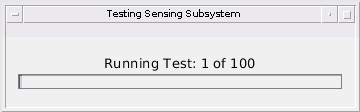

Error using fread
Invalid file identifier. Use fopen to generate a valid file identifier.

Error in Simulator_revB/read_from_file (line 757)
            read_data = fread(fileID,dtype);

Error in characterization_functions.USRP_compute_sensed_targets (

save_file_name = "attack_subsystem_spoofing_performance";
frames_to_compute = 40;
attack_start_frame = 11;
num_attack_frames = 15;

test_data_spoofing_performance = ...
                characterization_functions.USRP_get_spoofing_test_results( ...
                    num_cases, ...
                    frames_to_compute, ...
                    attack_start_frame, ...
                    num_attack_frames, ...
                    spoof_ranges, ...
                    spoof_velocities, ...
                    config_path, ...
                    save_file_name)

### Plot Test Case Information

read_file_name = save_file_name + ".csv";
characterization_functions.plot_spoofing_test_configurations(read_file_name);
characterization_functions.plot_spoofing_test_configuration_cdfs(read_file_name);

### Plot Test Case Results

% plot Range Spoofing Error
actual_values_idx = 1;
estimated_values_idx = 3;
abs_errors_idx = 5;
metric_title = "Range Spoofing";
metric_units = "m";
percentile = 85;
scale_factor = 1;
characterization_functions.generate_testing_summary_absolute_error(read_file_name,...
    actual_values_idx, ...
    estimated_values_idx, ...
    abs_errors_idx, ...
    metric_title, ...
    metric_units,...
    percentile,...
    scale_factor)
%Summary of Spoofing Velocity Performance
actual_values_idx = 2;
estimated_values_idx = 4;
abs_errors_idx = 6;
metric_title = "Velocity Spoofing";
metric_units = "m/s";
percentile = 85;
scale_factor = 1;
characterization_functions.generate_testing_summary_absolute_error(read_file_name,...
    actual_values_idx, ...
    estimated_values_idx, ...
    abs_errors_idx, ...
    metric_title, ...
    metric_units,...
    percentile,...
    scale_factor)